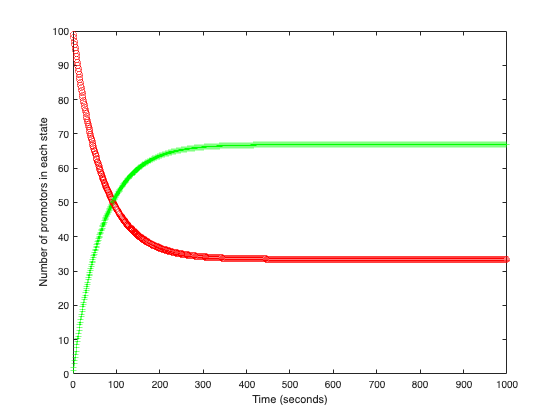

% Simulation of a simplified version of the model from Guido Collins et al., 2006
% Jun Allard allardlab.com

%% 1.1 Binding and unbinding of a TF to a promotor -- timestepping simulation

% parameters
kon = 0.01; % attachment rate, s^-1 uM^-1
koff = 0.005; % unbinding rate s^-1
C = 1.0; % microMolar, concentration of transcription factor

% set up a figure
figure; clf; hold on; box on;
xlabel('Time (seconds)')
ylabel('Number of promotors in each state')

% initial conditions
u_bound = 0;
u_unbound = 100; % the total number of times this promotor occurs in the system

dt = 1; % second EVERY SECOND, update the number of bound and unbound promotors
ntmax = 1000;
for nt=1:ntmax
    
    u_bound   = u_bound   + (+ kon*C*u_unbound - koff*u_bound)*dt;
    u_unbound = u_unbound + (- kon*C*u_unbound + koff*u_bound)*dt;
    
    plot(nt, u_bound, '+g')
    plot(nt, u_unbound, 'or')
    
end

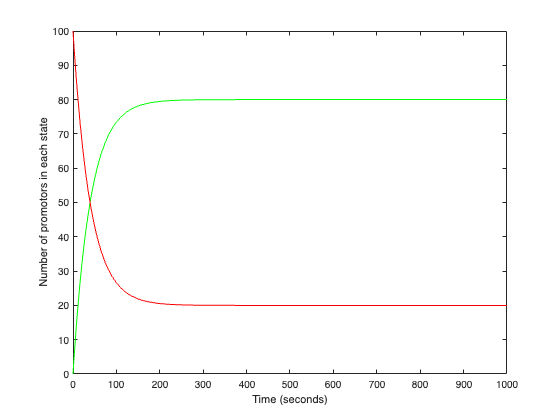


%% 1.2 Binding and unbinding of a TF to a promotor -- Matlab's built-in solver

% Now let's use Matlab's built-in ODE solver (which is faster and more accurate, but less flexible)

% parameters
kon = 0.01; % attachment rate, s^-1 uM^-1
koff = 0.005; % unbinding rate s^-1
C = 2.0; % microMolar, concentration of transcription factor

initialCondition = [0,100];

dbdt =@(b,u) +kon*C*u - koff*b;
dudt =@(b,u) -kon*C*u + koff*b;

dxdt = @(t,x)[dbdt(x(1),x(2));
              dudt(x(1),x(2))];

[T, X] = ode45(dxdt, [0.0,1000], initialCondition);

% set up a figure
figure; clf; hold on; box on;
plot(T,X(:,1),'-g'); % green for bound
plot(T,X(:,2),'-r'); % red for unbound
xlabel('Time (seconds)')
ylabel('Number of promotors in each state')

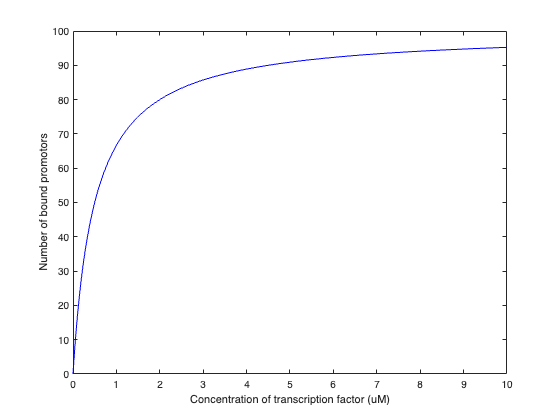



%% 1.3 Parameter sweep

paramArray = 0:0.01:10;
b_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)

    % parameters
    kon = 0.01; % attachment rate, s^-1 uM^-1
    koff = 0.005; % unbinding rate s^-1
    C = paramArray(iParam); % microMolar, concentration of transcription factor

    initialCondition = [0,100];
    
    dbdt =@(b,u) +kon*C*u - koff*b;
    dudt =@(b,u) -kon*C*u + koff*b;

    dxdt = @(t,x)[dbdt(x(1),x(2));
                  dudt(x(1),x(2))];

    [T, X] = ode45(dxdt, [0.0,1000], initialCondition);

    b_storage(iParam) = X(end,1);
    
end

figure; clf;
plot(paramArray,b_storage, '-b')
xlabel('Concentration of transcription factor (uM)')
ylabel('Number of bound promotors')


%set(gca, 'xscale', 'log')


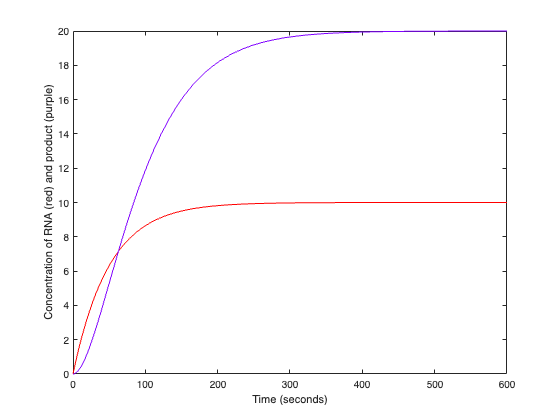



%% 2.1 Creation and destruction of mRNA and protein

% protein level

gamma_m = 0.2;
delta_m = 0.02;
gamma_p = 0.04;
delta_p = 0.02;

dmdt =@(m,p) +gamma_m   - delta_m*m;
dpdt =@(m,p) +gamma_p*m - delta_p*p;

initialCondition = [0,0];

dxdt = @(t,x)[dmdt(x(1),x(2));
              dpdt(x(1),x(2))];

[T, X] = ode45(dxdt, [0.0,600], initialCondition);

figure; clf; hold on; box on;
plot(T,X(:,1),'-r'); % red for RNA
plot(T,X(:,2),'-', 'color', [0.5 0 1]); % purple
xlabel('Time (seconds)')
ylabel('Concentration of RNA (red) and product (purple)')


%% 2.2 Combine the RNA model with promotor binding state

% parameters
kon = 0.001; % s^-1 uM^-1
koff = 0.0005; % s^-1

delta_m = 0.05;
gamma_p = 0.02;
delta_p = 0.01;

gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

I = 10; % concentration of inhibitory transcription factor (uM)
C = 10; % concentration of activatory transcription factor (uM)

M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
               +kon*I, -koff*I-kon*C,             0,   +koff;
               +kon*C,             0,   -koff-kon*I,   +koff;
                    0,        +kon*C,         kon*I, -2*koff];


dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par)   - delta_m*m;
dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

initialCondition = [1,0,0,0,0,0];

dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
               dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
               dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];

[T, X] = ode45(dxdt, [0.0,1000], initialCondition);

figure; clf; 

subplot(2,1,1);hold on; box on;
plot(T,X(:,1:4))
xlabel('Time (seconds)')
ylabel('Number of promotors in each state')

legend('Empty', 'repressor', 'activator', 'both')

subplot(2,1,2);hold on; box on;
plot(T,X(:,5),'-r'); % red for RNA
plot(T,X(:,6),'-', 'color', [0.5 0 1]); % purple
xlabel('Time (seconds)')
ylabel('Concentration of RNA (red) and product (purple)')



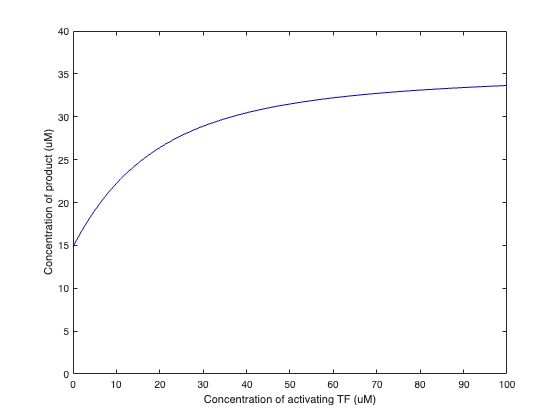


%% 2.3 Parameter sweep across activator concentration

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1

    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;

    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;

    I = 10; % concentration of inhibitory transcription factor (uM) % EDIT for HW1
    C = paramArray(iParam); % concentration of activatory transcription factor (uM) % EDIT for HW1

    M =@(t) [-kon*C-kon*I, +koff*I      ,          koff,       0;
                   +kon*I, -koff*I-kon*C,             0,   +koff;
                   +kon*C,             0,   -koff-kon*I,   +koff;
                        0,        +kon*C,         kon*I, -2*koff];


    dmdt =@(p0,pr,pa,par,m,p,t) +gamma_m(p0,pr,pa,par) - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,t) +gamma_p*m - delta_p*p;

    initialCondition = [1,0,0,0,0,0];

    dxdt = @(t,x)[M(t)*[x(1);x(2);x(3);x(4)];
                   dmdt(x(1),x(2),x(3),x(4),x(5),x(6));
                   dpdt(x(1),x(2),x(3),x(4),x(5),x(6))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') % EDIT for HW1
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);

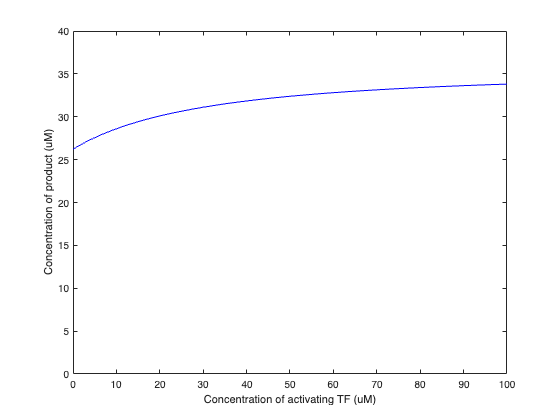


%set(gca,'xscale','log') % uncomment to make a log plot

%% 2.4 Positive feedback

paramArray = 0:1:100;

%paramArray = logspace(-1,3,200); % Uncomment to make a log plot

g_storage = zeros(size(paramArray));

for iParam=1:numel(paramArray)
    
    % parameters
    kon = 0.001; % s^-1 uM^-1
    koff = 0.0005; % s^-1
    
    delta_m = 0.05;
    gamma_p = 0.02;
    delta_p = 0.01;
    
    gamma_p2 = 0.1;
    
    I = 10; 
    C = paramArray(iParam); % external activatory transcription factor 
    
    M =@(pb,t) [-kon*(C+pb)-kon*I,   +koff*I           , koff       ,       0;
                           +kon*I,   -koff*I-kon*(C+pb),           0,   +koff;
                +kon*(C+pb)      ,                    0, -koff-kon*I,   +koff;
                        0        ,           kon*(C+pb),       kon*I, -2*koff];
    
    gamma_m =@(p0,pr,pa,par) 1.0*p0+0.0*pr+2.0*pa+1.0*par;
    
    dmdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_m(p0,pr,pa,par)     - delta_m*m;
    dpdt =@(p0,pr,pa,par,m,p,mb,pb) +gamma_p*m - delta_p*p;
    
    dmbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_m(p0,pr,pa,par)   - delta_m*mb;
    dpbdt =@(p0,pr,pa,par,m,p,mb,pb) + gamma_p2*mb - delta_p*pb;
    
    initialCondition = [1,0,0,0,0,0,0,0];
    
    dxdt = @(t,x)[M(x(8),t)*[x(1);x(2);x(3);x(4)];
               dmdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
               dpdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dmbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8));
              dpbdt(x(1),x(2),x(3),x(4),x(5),x(6),x(7),x(8))];
    
    [T, X] = ode45(dxdt, [0.0,100], initialCondition);
    
    g_storage(iParam) = X(end,6);
    
end

figure; clf;
plot(paramArray,g_storage, '-b')
xlabel('Concentration of activating TF (uM)') 
ylabel('Concentration of product (uM)')
set(gca,'ylim', [0,40]);


%set(gca,'xscale','log') % uncomment to make a log plot

